## Lineal Regression

Analyzes the relationship between a dependent variable **y** and an regressive variable **x**, by approximating **y** as a function of **x**.

Expression: yi = beta0 + beta1 * xi1 + beta2 * xi2 + ... + betap * xip = **x**i^T * **beta**

where:

- **x**i: Vector (p+1 x 1) with regressive variables

- **beta**: Vector (p+1 x 1) with unknown variables

with:

- i = 0, 1, 2, ..., n

Simplified expression: **y** = X * **beta**

where:

- X = [ x1^T, x2^T, ..., xn^T ]^T

x_data = [2; 5; 5; 8];
y_data = [3; 4; 6; 7];
data = [x_data y_data]                                  % Grouped data

data =      2     3
     5     4
     5     6
     8     7


n = length(data);                                       % Data length (n)

X = [];
for i = 1:n
    xi = [1 x_data(i)];                                 % xi = [1, xi1, xi2, ..., xip]^T
    X = [X; xi];
end
X

X =      1     2
     1     5
     1     5
     1     8


y_real = y_data                                         % y = [y1, y2, .... yn]^T

y_real =      3
     4
     6
     7


To solve for **beta**

where:

- beta = [ beta0, beta1, beta2, ..., betap ]^T

Its necessary to:

- Take the difference between the real value and the predicted value ei: ei = yi - **x**i^T * **beta**

- Take the square of the difference of ei and sum all n differences: Sum (from i=1 to n) of [ ei^2 ]

where:

- **e** = **y** - X * **beta**

- The sum of squared differences is denoted as SRC(**beta**) = **e**^T * **e**

By taking double derivative with respect to betaj and equating to zero, with j = 0, 1, 2, ..., p, we have:

Expression: **beta** = [ X^T * X ]^(-1) * X^T * **y**

beta = (X.' * X)^(-1) * X.' * y

beta =     1.6667
    0.6667


y_predicted = X * beta                                  % Solving for predicted real values

y_predicted =     3.0000
    5.0000
    5.0000
    7.0000


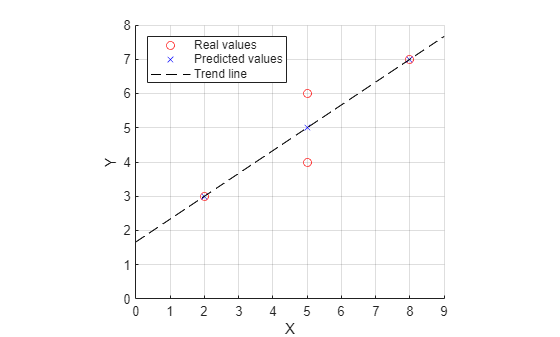

% Ploting data
figure;
hold on;
plot(x_data, y_real, 'ro');                             % Real values
plot(x_data, y_predicted, 'bx');                        % Predicted values
plot([0 9], [beta(1), beta(1) + beta(2)*9], 'k--');     % Trend line
grid on; axis equal; legend('Real values', 'Predicted values', 'Trend line', 'Location', 'northwest');
xlim([0 9]); ylim([0 8]); xticks(0:9); yticks(0:8);
xlabel('X'); ylabel('Y');
hold off;